# How does an action potential propagate down a long axon?

Neurons are not points. In humans, some have axons stretching up to around 1 meter. The membrane potential varies across such distances. It takes time for an action potential to propagate down an axon. (This is important to our understanding of cell-to-cell communication: there is always a delay between an action potential being generated in a presynaptic cell and the postsynaptic cell receiving input.)

To study this, we'll create an axon, inject current at one end, and plot the membrane potential vs position at several time points.

## Get started

To get started we must create our NEURON object and load `stdrun.hoc`. Just to be safe, we'll also clear all MATLAB values and discard any existing sections.

clear;
n = neuron.start_session();     % Initialize the NEURON session.
n.reset_sections();             % Reset topology.
n.load_file("stdrun.hoc");      % load the standard run control

## The model

We'll create a long, thin axon.

axon = n.Section("axon");
axon.length = 10000;   % 10 mm
axon.set_diameter(2);  % 2 um

Let's add the ion channels:

axon.insert("hh");

and setup a current clamp injection at the beginning of the axon starting at the beginning of the simulation (in a "real" model, we may want to wait a bit to make sure the system is stable before starting our experiment):

ic = n.IClamp(axon(0));
ic.del = 0;    % ms -- in Python this would be: ic.delay = 0
ic.dur = 0.2;  % ms
ic.amp = 2.0;  % nA

By default, NEURON uses one compartment (segment) for each section, but that means it would only compute one value of v, which wouldn't be enough to capture the spatial variation. To allow for such variation, we must divide the section into many segments:

axon.nseg = 101

axon =   Section with properties:

     mech_list: ["morphology"    "capacitance"    "pas"    "extracellular"    "fastpas"    "na_ion"    "k_ion"    "hh"]
    range_list: ["v"    "i_membrane_"    "diam"    "cm"    "i_cap"    "g_pas"    "e_pas"    "i_pas"    "xraxial"    "xg"    "xc"    "e_extracellular"    "i_membrane"    "vext"    "g_fastpas"    "e_fastpas"    "ena"    "nai"    "nao"    "ina"    …    ]
        length: 10000
          nseg: 101
          name: "axon"


We use an odd number of segments to ensure that there is a segment whose center is at the center of the `axon`.

## Instrumentation

We'll want a `RangeVarPlot` that can do the actual measurements of a state variable -- here `v` -- along a path between two points, here `axon(0)` and `axon(1)` although there is no need for them to be on the same section.

rvp = n.RangeVarPlot("v");
rvp.begin(axon(0));
rvp.end(axon(1));

The above works in Python as well, substituting `h` for `n`, but there we can also specify everything on one line: 

`    rvp = h.RangeVarPlot("v", axon(0), axon(1))`

## Run the experiment

We'll start at time 0, plot potential vs position along the path (here: just distance from the beginning of the axon) at several time points:

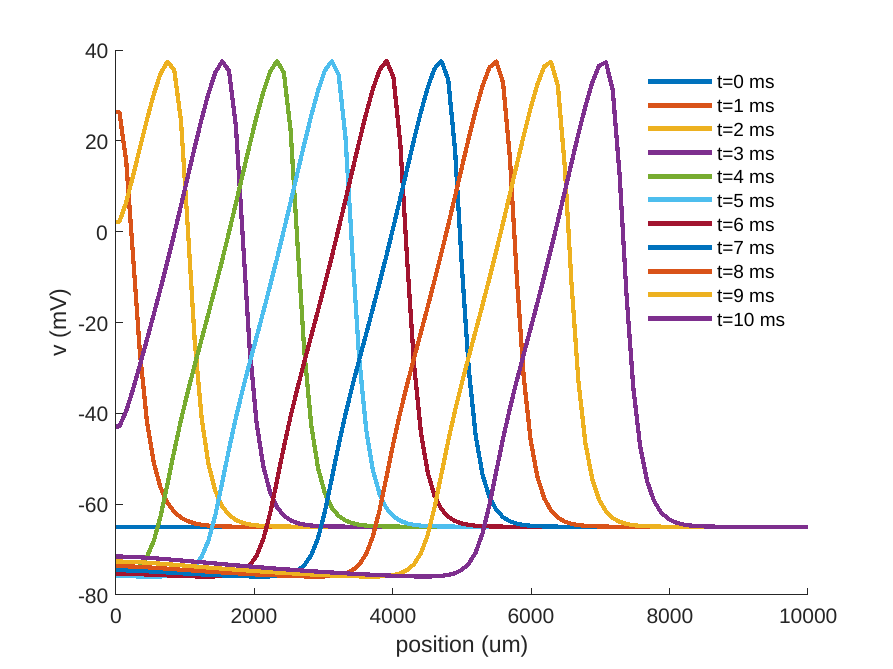

n.finitialize(-65);
t_vals = 0:10;
for t = t_vals
    n.continuerun(t);
    rvp.plot("LineWidth", 2);
    hold on;
end
xlabel("position (um)");
ylabel("v (mV)");
legend(arrayfun(@(t){"t="+t+" ms"}, t_vals));
legend boxoff;
box off;
hold off;

If you're used to thinking of voltage plotted against time, this may seem backwards at first, but since the action potential started at position 0, for each curve, that position is the point farthest along (in time) of the action potential.